# Doppio Pendolo

Definiamo i parametri che manterremo costanti per tutta l'esercitazione:

clear;
clearvars;
m1 = 4;
m2 = 2;
l1 = 6;
l2 = 4;
g = 9.81;
dt = (0:0.05:100);
%omega1,omega2, theta1, theta2
x0 =[pi/2,0,0,0];
opts = odeset('RelTol',1e-8,'AbsTol',1e-10);

Integriamo numericamente il sistema:

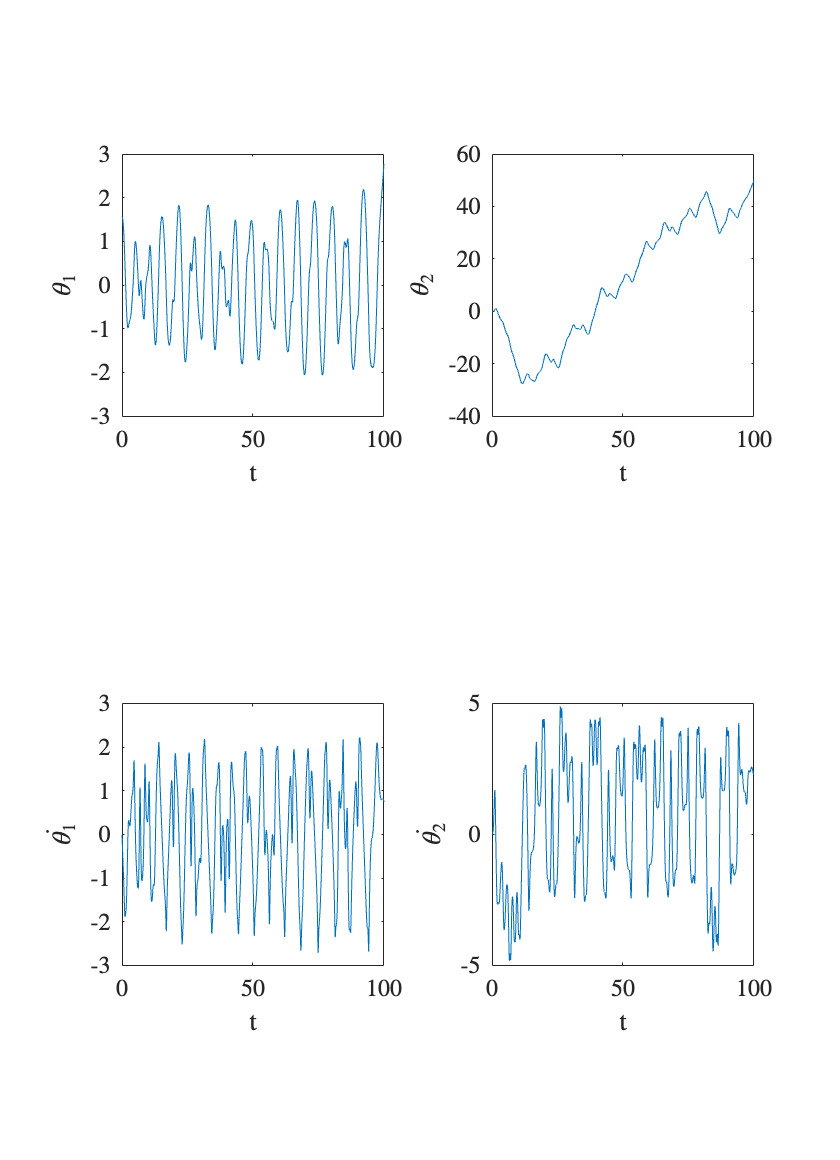

[t,x] = ode45(@(t,x)sis_non_lineare(x,t,m1,m2,l1,l2),dt,x0,opts);
prima_ris = figure;
set(gcf,'PaperUnits','centimeters');
set(gcf,'Position',[100,100,420,580]);

subplot(2,2,1);
plot(t,x(:,1));
axis square;
xlabel("t", 'Interpreter','latex');
ylabel("$\theta_1$",'Interpreter','latex');
set(gca,'TickLabelInterpreter', 'latex','fontsize',12);

subplot(2,2,2);
plot(t,x(:,2));
axis square;
xlabel("t", 'Interpreter','latex');
ylabel("$\theta_2$",'Interpreter','latex');
set(gca,'TickLabelInterpreter', 'latex','fontsize',12);

subplot(2,2,3);
plot(t,x(:,3));
axis square;
xlabel("t", 'Interpreter','latex');
ylabel("$\dot{\theta_1}$",'Interpreter','latex');
set(gca,'TickLabelInterpreter', 'latex','fontsize',12);

subplot(2,2,4);
plot(t,x(:,4));
axis square;
xlabel("t", 'Interpreter','latex');
ylabel("$\dot{\theta_2}$",'Interpreter','latex');
set(gca,'TickLabelInterpreter', 'latex','fontsize',12);